# The Significance of Cognitive Boundaries in Episodic Memory:

# DANDI Data Storytelling with MatNWB

*Written by: Marielle L. Darwin, PhD *

This live script utilizes the MatNWB library to analyze human single-neuron data that has determined the important role of cognitive boundaries in episodic memory formation. 

#### Resources 

The following resources are publically available to conduct the analyses and reproduce the figures in this live script: 1) Public DANDI [dataset](https://dandiarchive.org/dandiset/000207?search=00207&pos=1) (dataset ID: 000207) [1]; 2) Accompanying [manuscript](https://www.nature.com/articles/s41593-022-01020-w#Fig3); and 3) Accompanying [utility code](https://github.com/rutishauserlab/cogboundary-zheng). 

1) This live script used data from Subject 1 available in the DANDI [dataset](https://dandiarchive.org/dandiset/000207?search=00207&pos=1). To access and download this data, follow the link to the DANDI [dataset](https://dandiarchive.org/dandiset/000207?search=00207&pos=1). On the right under Dandiset Actions, choose 'Files', then select the 'sub-1' folder. Download the file 'sub-1_ses-1_ecephys+image.nwb' found [here](https://dandiarchive.org/dandiset/000207/0.220721.1915/files?location=sub-1). 

2) The accompanying [manuscript](https://www.nature.com/articles/s41593-022-01020-w#Fig3) [2] details the rationale for the study and analyses, which are summarized in the Background section in this live script. The complete analysis plan and figures can be found within this manuscript as well.

3) The authors of the study have released publically available [utility code](https://github.com/rutishauserlab/cogboundary-zheng) to facilitate the reproduction of sections of the figures included in the manuscript.

## Overview

In this live script, we are going to explore a [study](https://www.nature.com/articles/s41593-022-01020-w#citeas) that aimed to explore the neural basis of episodic memory. The concepts discussed in this study are defined and discussed, followed by an explanation of the authors' chosen methodology. Two figures from the manuscript produced from the study are reproduced.

The live script is accompanied by a live function `raster_encoding_BAligned.mlx `that allows the user to reproduce Figure 3a.

In addition, the following three files are needed at various points in this analysis:

- `setup.m` is executed on `line 1 `to create the file path structure.

- `nwb_read_unit.m` is executed on `line 40` to locate spikes within each cluster for the selected cell.

- `boundedline.m` is executed within the live function `raster_encoding_BAligned.mlx `on` lines 124-129 `to plot lines with shaded error/confidence bounds.

#### Table of Contents

## Background

### Episodic Memory is a Critical Component of Day to Day Life

Episodic memory is our ability to remember specific experienced events.  

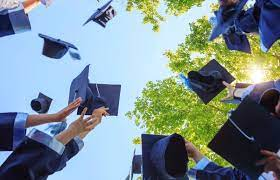                    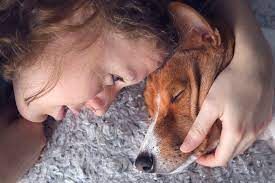                    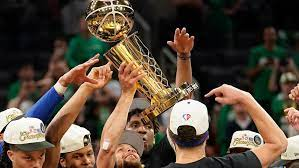 

We remember these occurances as a continuous sequence of experiences; however, they are represented in our minds as discrete episodes, or events, that are woven together to paint the complete picture. 

Events are the building blocks of our ability to remember context-specific information. Yet, it is currently unknown how the beginnings and ends of events are marked as distinct from one another to differentiate between separate occasions. 

Determining the mechanisms behind the separation of events will help to better understand the sequences that promote strong memory as well as those that relate to poor memory.

### Cognitive boundaries shape the transformation from continuous experience to distinct events

Just as spatial boundaries help us to differentiate between different points in space, cognitive boundaries are suggested to help us differentiate between different points in time. Specifically, cognitive boundaries are thought to bookend event-specific representations of our experiences. 

Neural data has shown large-scale patterns of activity changes in the human brain surrounding event boundaries. While these findings support the notion that cognitive boundaries are the mechanism that separates events in our minds, many questions remain, such as:

- **What is the relationship between cognitive boundaries and components of memory?**

- **What are the underlying neural mechanisms of cognitive boundaries?**

This study was the first that aimed to answer these questions with single-cell level analyses in humans. This methodology afforded higher spacial and temporal resolution than has been achieved previously. 

## Methodology

How can we best answer the questions stated above? 

What is the relationship between cognitive boundaries and components of memory?

Subjects completed a three-part memory task to test the relationship between cognitive boundaries and encoding, scene recognition, and time discrimination.

Part 1: Encoding. Subjects watched video clips with three boundary conditions. 

- No boundary (NB): A continuous video clip

- Soft boundary (SB): A clip that cuts to a scene from the same movie

- Hard boundary (HB): A clip that cuts to a scene from a different movie

Part 2: Scene recognition. Single frames of clips were shown to subjects. Some frames were from clips shown in encoding, some frames were novel.

- Subjects were asked to identify whether they had seen the frames before ("old") or not ("new")

- Subjects were asked to rate how confident they were in their selection on a Likert scale

Part 3: Time discrimination. In each trial, two frames separated by wither NB, SB, or HB extracted from the same video clip were shown to subjects.

- Subjects were asked to indicate which of the frames occured first (earlier in time) in the videos watched during encoding.

What are the underlying neural mechanisms of cognitive boundaries?

- This inquiry was answered by recording single-neuron activity from subjects while completing the three-part memory task

- Recordings from the medial temporal lobe (MTL) were primarily used in analyses

- Neural mechanisms investigated included: spike firing rates and latencies, mean resultant length (MRL) for theta band phases of spikes, spike density estimates from all recorded MTL cells across all subjects to determine neural state trajectories, and the size of state shifts as a function of time

## MatNWB as a Data Analysis Tool

All data was stored in Neurodata Without Borders (NWB) format. Each NWB file contains the complete data and metadata for a single session from a single subject. 

### Requirements

- Download [MatNWB interface library](https://neurodatawithoutborders.github.io/matnwb/#setup): Used to read and write NWB files with MATLAB

- [Dataset](https://dandiarchive.org/dandiset/000207/0.220721.1915/files?location=) from one subject obtained from DANDI. The subject file used in this script is 'sub-1_ses-1_ecephys+image.nwb' found [here](https://dandiarchive.org/dandiset/000207/0.220721.1915/files?location=sub-1). 

## Data Preparation and Exploration

Steps must be taken to prepare the data for analyses and explore the dataset before we can begin to answer our research questions.

### 1. Set path structure and add paths

Run setup.m file to set path structure from pop-up UIs with user input.

setup.m

Unable to resolve the name setup.m.

### 2. Select subject NWB file

Set the subject session number to plot. The subject session number used in this live script is `1`. 

%3


% % Set subject to plot + what to plot - make into f(x)
%     % User input subject + plot type
%     prompt = {['Input subject ID for plot']};
%     dlgtitle = 'Which session would you like to plot?';
%     dims = [1 35]; % dimensions of dlg box
%     definput = {'1'};
%     answer = inputdlg(prompt,dlgtitle,dims,definput); 
%          
% 
%     % Fill variables with dlg input                                            
%     CBID = str2num(answer{1}); %don't convert to num
%     CBID2 = "1";

### 3. Import and explore the NWB file

The function `nwbRead` from the matNWB library is used to read files into MATLAB

fName_in = "sub-" + CBID2 + "_ses-" + CBID2 + "_ecephys+image.nwb"; %USE when fixed
   
% Import file
nwbData = nwbRead(fullfile(basepathData, filesep, fName_in)) 

#### What is in the NWB file?

This NWB file contains data and metadata for a single session of an experiment for a single subject.

We will be extracting neural data from the `general_extracellular_ephys_electrodes` and the `units `objects within the NWB file to conduct our analyses.

`general_extracellular_ephys_electrodes` 

- Channel IDs

- Names of brain areas

`units`

- Spike data + indexes

- Electrodes

- Cluster groups

Let's explore the file contents. One way to do so is to use `util.nwbTree`, which creates a pop-up user interface wherein you can browse through the structure of the file to find where the data and metadata are located that you wish to extract.

util.nwbTree(nwbData);

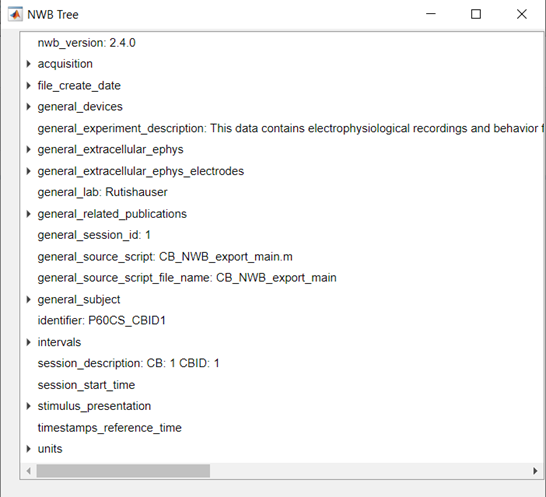

You can also hover over a variable name in this live script for a small pop-up that reveals the variable contents.

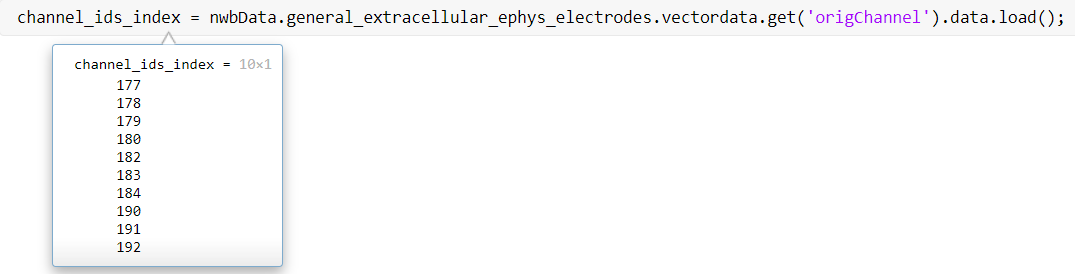

### 4. Load neural data into MATLAB from NWB file

#### What neural data will we need to extract? 

Spike data

all_spike_data = nwbData.units.spike_times.data.load();
spike_data_indexes = nwbData.units.spike_times_index.data.load();

Channel IDs 

channel_ids_index = nwbData.general_extracellular_ephys_electrodes.vectordata.get('origChannel').data.load();

Electrodes

cell_electrodes = nwbData.units.electrodes.data.load();

Names of brain areas

brain_areas_index = nwbData.general_extracellular_ephys_electrodes.vectordata.get('location').data.load;

Cluster groups

clusterIDs = nwbData.units.id.data.load;   % All available ID's (clusters)

#### Now, use this data to create variables we will need for analyses 

elec_index = [cell_electrodes]+1;

Match the channel IDs to the electrode

channel_ids = channel_ids_index(elec_index);

Match the brain area name to the electrode

brain_areas = brain_areas_index(elec_index,:);

## Reproducing Key Figures

A series of analyses were conducted to determine 1) the relationship between cognitive boundaries and components of memory and 2) the underlying neural mechanisms of cognitive boundaries. 

### **Fig. 3: Boundary cells and event cells demarcate different types of episodic transitions.**

#### ***Are there MTL neurons that exhibit changes in activity following cognitive boundaries during encoding?***

What this information would tell us: Answering this question will help us to understand what is happening at the level of single neurons when cognitive boundaries are introduced. Are there specific cells that respond differently to event boundaries? Let's explore and plot the data to find out.

In this section, we will determine if there are cells that respond differently to NBs, SBs, or HBs.

The following code accompanies the `CB_analysis_Dandi_main.m` script found in the `cogboundary-zheng-main` Github repository. 

#### Parameters for analyses and plotting

We will use many of the variables computed earlier in the script, but now we will compute a few more that are needed for this specific analysis. 

% Assign subject ID to variable for analyses and plotting
CBID_toPlot = CBID; 

Now, we will create the raster plot for **Figure 3a**. Raster plots are helpful to visualize the frequency of spike firing to examine the trial-by-trial variability in responses. This raster plot will detail neuronal responses from a boundary cell from the hippocampus during the encoding stage of the behavioral task.

Finish setting the plot parameters.

*[input live controls]*

% 2.07
%  Resolution of raster plot
bin_width_raster = 0.01; % default is 0.01=10ms

ans = 2.0700

% Set bin width 
bin_width_fr = 0.2;      % 200ms per bin
% Logical indicator to plot data or not
plot_flag = 'on';

#### For each selected cell, locate spikes within each cluster and plot

This section utilizes the `nwb_read_unit.m` file.

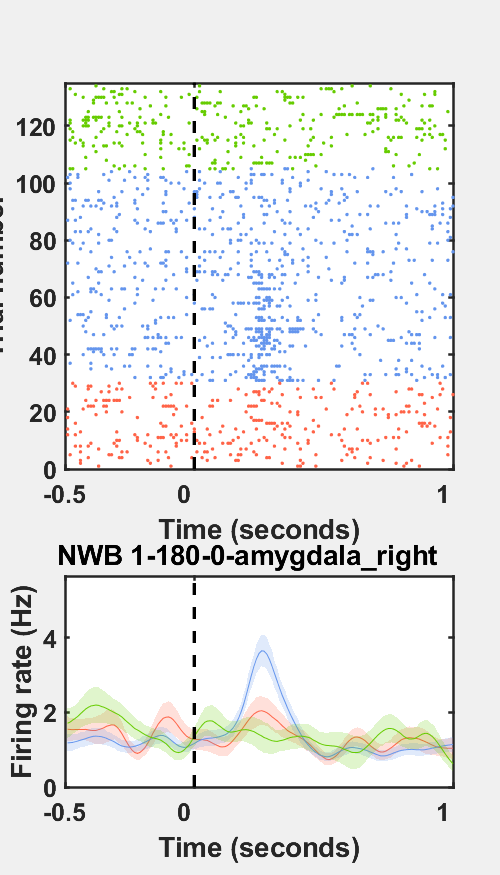

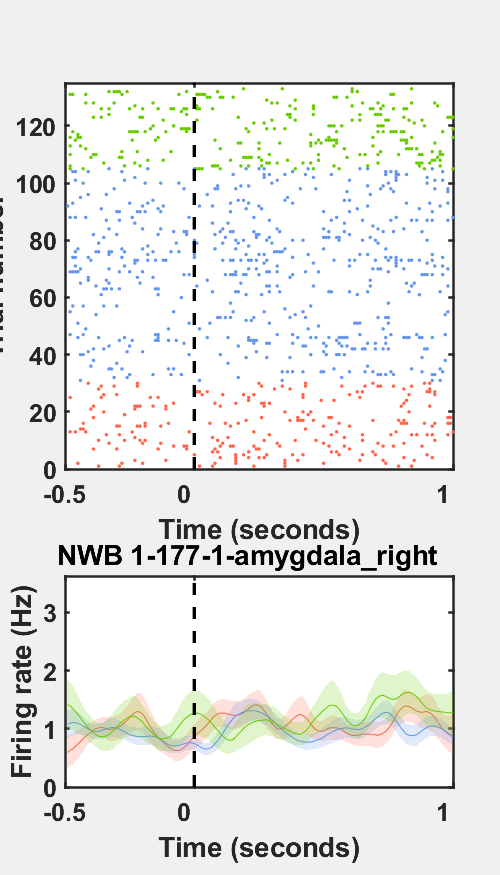

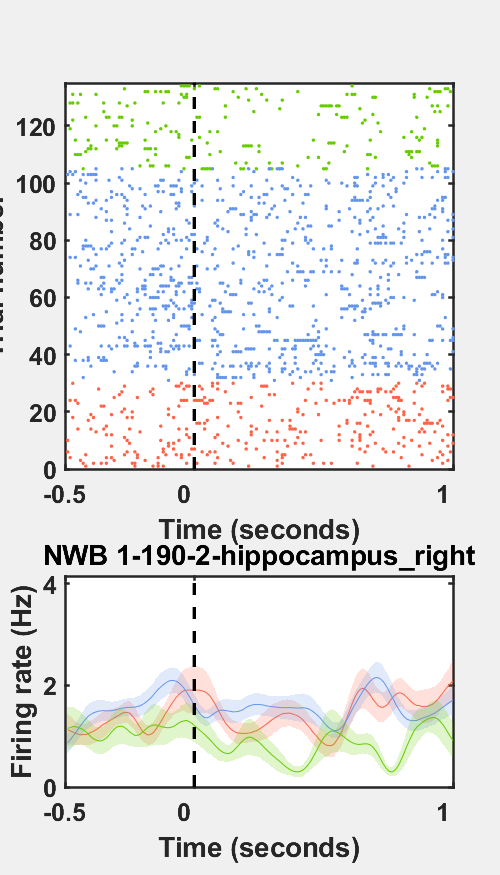

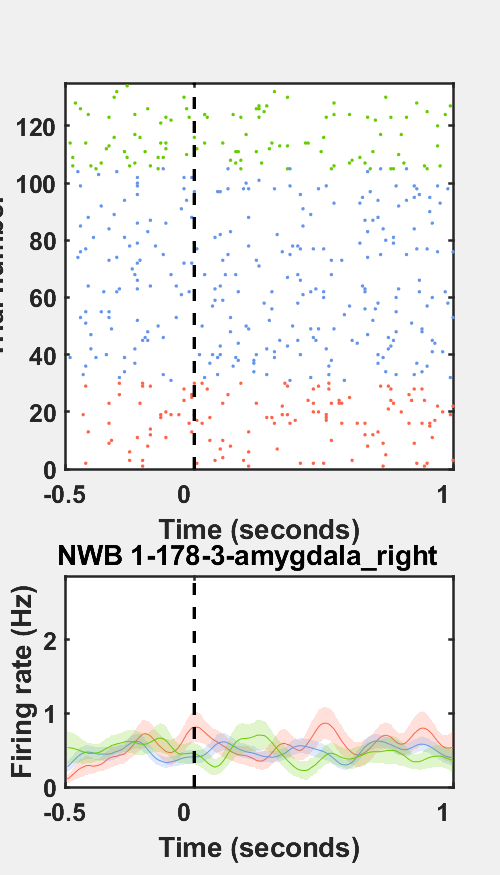

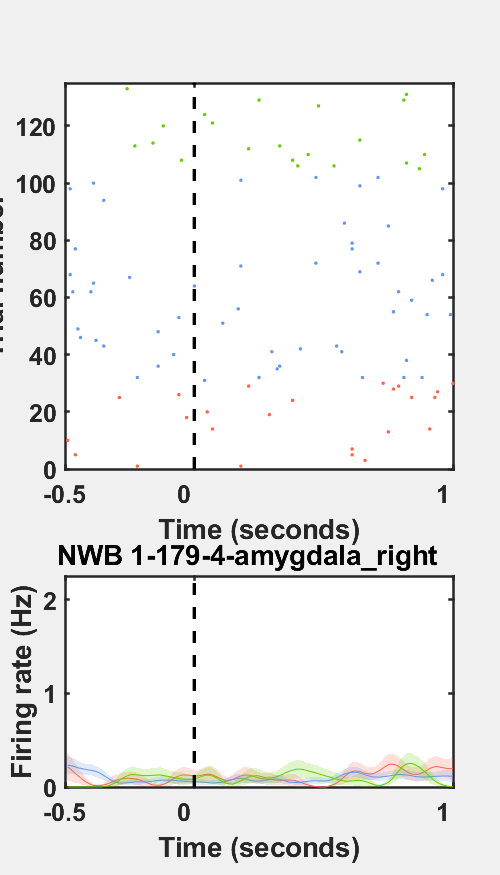

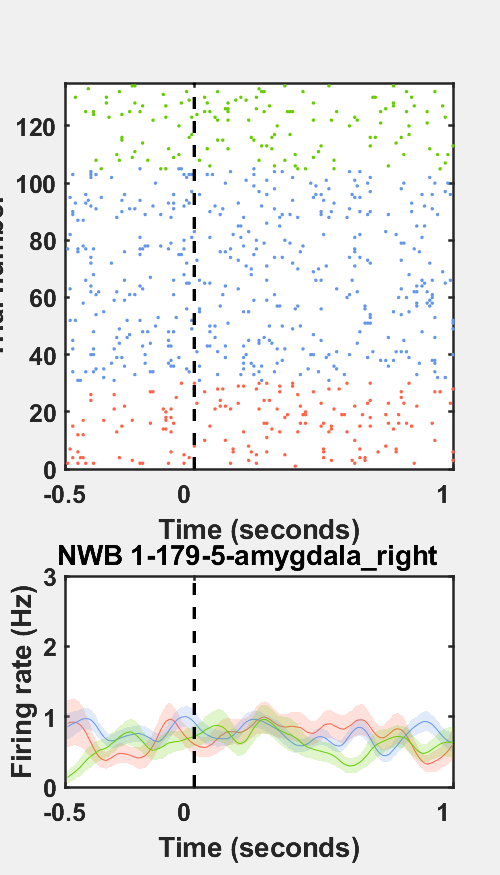

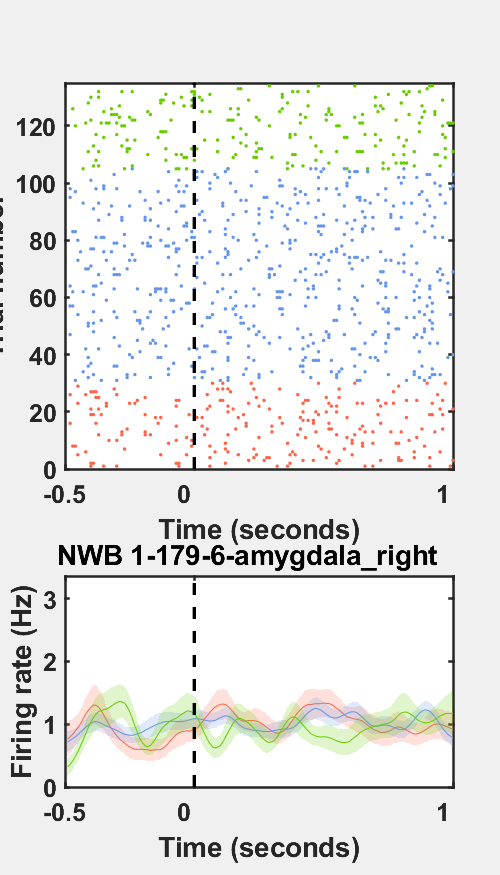

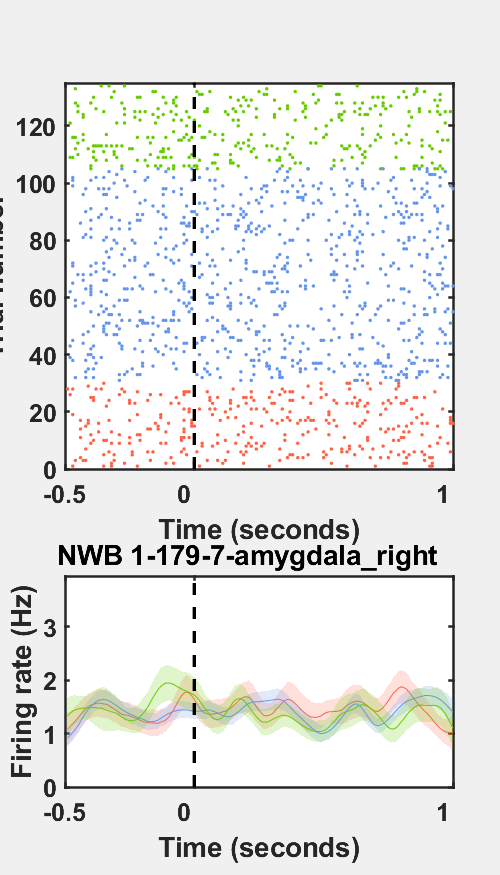

for i = 1:length(clusterIDs)   % All cells
%for i = 1:2  % Subset of cells
    
    % Locate spikes that belong to this cluster
        timestampsOfCell = nwb_read_unit(nwbData.units.spike_times_index, ...
            nwbData.units.spike_times, clusterIDs(i)+1); % Timestamps of cluster
        channelid =  channel_ids(i);
        cellNr = clusterIDs(i); % Cell number
        brainAreaOfCell = brain_areas(i,:);
        currentCell = cellNr;
    
    % Raster plot of cell
        % Encoding, boundary aligned
        raster_encoding_BAligned(nwbData, timestampsOfCell, ...
            channelid, cellNr, brainAreaOfCell, bin_width_raster, bin_width_fr, plot_flag);
end

Here is an example of a raster plot and a spike tuning curve for the encoding period, boundary aligned:

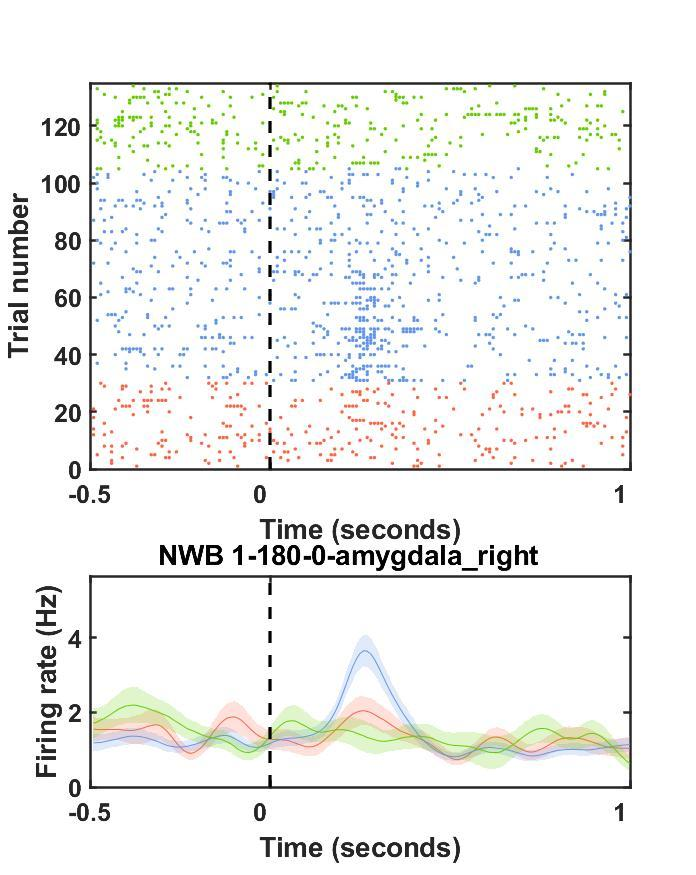

**Key: **The trials with NB are in green, trials with SB are in blue, and trials with HB are in red. 

The raster plot shows us that some cells in the MTL responded more to SB and HB than NB. Specifically, this subset had increased firing rate within 300 ms following both SBs and HBs but not NBs. These cells are termed boundary cells.

Although not shown in this figure, there were another subset of cells that were only responsive (i.e., increased firing rate) following HBs compared to SBs and NBs. These cells are termed event cells. 

### Main takeaway: Two types of cells within the MTL were differently affected by cognitive boundaries.

Boundary cells were responsive to both HBs and SBs, but not NBs, while event cells were only responsive to HBs.

These findings help to paint a picture of how specific events are formed and coded for within the brain. In the memory task, HBs were simulated by showing a clip of one movie followed by a clip of a completely different movie to represent an abrupt change in stimulus content and context. The finding that event cells were only responsive to HBs suggests that they function to detect a stark disruption of the conceptual narrative, or in other words, the transition between two different episodes. 

## References

[1] DANDI dataset ID: 000207. 

Cite as: Zheng, Jie; Schjetnan, Andrea; Yebra, Mar; Gomes, Bernard; Mosher, Clayton; Kalia, Suneil; Valiante, Taufik; Mamelak, Adam; Kreiman, Gabriel; Rutishauser, Ueli (2022) Data for: Neurons detect cognitive boundaries to structure episodic memories in humans (Zheng et al., 2022, Nat Neuro in press) (Version 0.220721.1915) [Data set]. DANDI archive. https://doi.org/10.48324/dandi.000207/0.220721.1915

[2] Zheng, J., Schjetnan, A.G.P., Yebra, M. *et al.* Neurons detect cognitive boundaries to structure episodic memories in humans. *Nat Neurosci* **25**, 358–368 (2022). https://doi.org/10.1038/s41593-022-01020-w